# ASSIGNMENT 5

Gianpaolo Mastroiacovo (ge28tud)

Antonio Di Giovanni (03743324)

Data(25/05/2021)

## Exercise 5.1)

#### *a)*

Being our objective function the maximization of a difference, the second term has to be forced to the smallest possible value. In case $t-R_s$ assumes a negative value, $z_s$ will be set to $0$, otherwise, if $t-R_s$ is positive, the solver will assign $z_s$ exactly that value and not a higher one because it's more "convenient".

#### *b)*

#### 
$$\begin{array}{l}
\mathrm{First}\;\mathrm{case}:\\
F\left(F_R^{-1} \left(\alpha \right)\right)>\alpha \\
F_R^{-1} \left(\alpha \right)=R_I ,\mathrm{with}\;\sum_{s=1}^I p_i >\alpha \;\;\;\;\left(1\right)\\
\mathrm{so}\;F\left(R_I \right)>\alpha \\
\mathrm{We}\;\mathrm{want}\;\mathrm{to}\;\mathrm{prove}\;\mathrm{that}\;\mathrm{if}\;t<F_R^{-1} \left(\alpha \right)-\epsilon ,\mathrm{than}\;t\;\mathrm{is}\;\mathrm{not}\;\mathrm{optimal}\;\mathrm{for}\;\mathrm{our}\;\mathrm{objective}\;\mathrm{function}\;\;\max \;t-\alpha^{-1} \left(\sum_{s=1}^I z_s p_s \right)\ldotp \\
t<F\left(R_I \right)-\epsilon \Rightarrow t+\frac{\epsilon }{2}<F\left(R_I \right)-\frac{\epsilon }{2}\\
\mathrm{The}\;\mathrm{objective}\;\mathrm{function}\;\mathrm{can}\;\mathrm{be}\;\mathrm{then}\;\mathrm{written}\;\mathrm{as}\;\mathrm{follows}:\\
t+\frac{\epsilon }{2}-\alpha^{-1} \left(p_1 \left(F_R^{-1} \left(\alpha \right)-R_1 -\frac{\epsilon }{2}\right)+\;,\;\ldotp \ldotp \ldotp \;,\;+p_I \left(F_R^{-1} \left(\alpha \right)-R_I -\frac{\epsilon }{2}\right)+0\;,\ldotp \ldotp \ldotp ,0\;\right)\;\\
F_R^{-1} \left(\alpha \right)\;\;\mathrm{and}\;{\;R}_I \;\mathrm{cancel}\;\mathrm{out}\;\mathrm{as}\;\mathrm{per}\;\left(1\right),\mathrm{so}\;\mathrm{we}\;\mathrm{notice}\;\mathrm{that}\;\mathrm{the}\;\mathrm{summation}\;\mathrm{keeps}\;\mathrm{growing}\;\mathrm{till}\;I-1,\mathrm{while}\;\mathrm{all}\;\mathrm{the}\;\mathrm{addends}\;\mathrm{from}\;I\;\mathrm{to}\;S\;\mathrm{will}\;\mathrm{be}\;\mathrm{zeros}\;\left(2\right)\ldotp \\
\mathrm{As}\;\mathrm{a}\;\mathrm{consequence},\mathrm{the}\;\mathrm{right}\;\mathrm{side}\;\mathrm{of}\;\mathrm{the}\;\mathrm{equation}\;\mathrm{will}\;\mathrm{only}\;\mathrm{grow}\;\mathrm{by}\;\mathrm{an}\;\mathrm{amount}\;\mathrm{lower}\;\mathrm{than}\;\frac{\epsilon }{2}\ldotp \\
\mathrm{As}\;F\left(R_{I-1} \right)<\alpha ,\;\alpha^{-1} \left(\sum_{s=1}^{I-1} \left(F_R^{-1} \left(\alpha \right)-R_s -\frac{\epsilon }{2}\right)p_s \right)\\
t+\frac{\epsilon }{2}-\alpha^{-1} \left(\sum_{s=1}^{I-1} \left(F_R^{-1} \left(\alpha \right)-R_s -\frac{\epsilon }{2}\right)p_s \right)\\
t+\frac{\epsilon }{2}-\alpha^{-1} \left(\sum_{s=1}^{I-1} \left(F_R^{-1} \left(\alpha \right)-\frac{\epsilon }{2}\right)p_s -\sum_{s=1}^{I-1} R_s p_s \right)\\
\frac{\left(F_R^{-1} \left(\alpha \right)-\frac{\epsilon }{2}\right)\sum_{s=1}^{I-1} p_s }{\alpha },\mathrm{following}\;\mathrm{the}\;\mathrm{conclusion}\;\mathrm{above}\;\left(2\right),\;\mathrm{we}\;\mathrm{can}\;\mathrm{state}\;\mathrm{that}\;\frac{\sum_{s=1}^{I-1} p_s }{\alpha }\;<\;1=\sigma \\
t+\frac{\epsilon }{2}-\alpha^{-1} \left(\sum_{s=1}^{I-1} \left(F_R^{-1} \left(\alpha \right)-\frac{\epsilon }{2}\right)p_s -\sum_{s=1}^{I-1} R_s p_s \right):\mathrm{for}\;\mathrm{values}\;\mathrm{of}\;t<F_R^{-1} \left(\alpha \right)-\epsilon ,\mathrm{before}\;\mathrm{reaching}\;F_R^{-1} \left(\alpha \right),\mathrm{the}\;\mathrm{vaue}\;\mathrm{of}\;\mathrm{the}\;\mathrm{objective}\;\mathrm{function}\;\mathrm{grows}\ldotp \\
t+\frac{\epsilon }{2}-\left(\left(t+\frac{\epsilon }{2}\right)\sigma -\frac{\sum_{s=1}^{I-1} R_s p_s }{\alpha }\right)\;\\
\\
\mathrm{In}\;\mathrm{case}\;t>F_R^{-1} \left(\alpha \right)+\epsilon ,\;\mathrm{we}\;\mathrm{will}\;\mathrm{analyze}\;\mathrm{how}\;\mathrm{the}\;\mathrm{function}\;\mathrm{varies}\;\mathrm{when}\;\mathrm{reducing}\;t\;\mathrm{by}\;\frac{\epsilon }{2}\ldotp \\
t-\frac{\epsilon }{2}-\alpha^{-1} \left(\sum_{s=1}^S z_s p_s \right),\mathrm{where}\;z_s =\max \left\lbrace 0,F_R^{-1} \left(\alpha \right)-R_s +\frac{\epsilon }{2}\right\rbrace \\
\mathrm{As}\;F_R^{-1} \left(\alpha \right)=R_I ,\mathrm{we}\;\mathrm{have}\;\\
t-\frac{\epsilon }{2}-\alpha^{-1} \left(\left(\sum_{s=1}^{I-1} z_s p_s \right)+\frac{\epsilon }{2}{\;p}_I \right)\\
t-\frac{\epsilon }{2}-\frac{\sum_{s=1}^{I-1} \left(F_R^{-1} \left(\alpha \right)+\frac{\epsilon }{2}-R_s \right)p_s }{\alpha }-\frac{\epsilon \;p_I }{2}\\
t-\frac{\epsilon }{2}-\left(\frac{\left(t-\frac{\epsilon }{2}\;\right)\sum_{s=1}^{I-1} p_s }{\alpha }-\frac{\sum_{s=1}^{I-1} R_s p_s }{\alpha }-\frac{\epsilon \times p_I }{2}\right)\\
\mathrm{with}\;\frac{\sum_{s=1}^{I-1} p_s }{\alpha }<1=\sigma \\
t-\frac{\epsilon }{2}+\left(-\left(t-\frac{\epsilon }{2}\right)\sigma +\frac{\epsilon \times p_I }{2\alpha }+\frac{\sum_{s=1}^I R_s p_s }{\alpha }\right)\\
\\
\;
\end{array}$$


#### *c)*


$$t-\alpha^{-1} \left(\sum_{s=1}^S z_s p_s \right)=\alpha^{-1} \left(\alpha t\left(-\sum_{s=1}^S z_s p_s \right)\right)=\alpha^{-1} \left(p_1 \left(t-z_1 \right)+p_2 \left(t-z_2 \right)+,\ldotp \ldotp \ldotp ,+{\;p}_{I-1} \left(t-z_{I-1} \right)+,\ldotp \ldotp \ldotp \right)$$


 
$$\begin{array}{l}
\mathrm{The}\;\mathrm{next}\;\mathrm{element}\;\mathrm{of}\;\mathrm{the}\;\mathrm{summation}\;\mathrm{would}\;{\mathrm{be}\;p}_i z_i ,\mathrm{but}\;\mathrm{the}\;\mathrm{remaining}\;\mathrm{part}\;\mathrm{of}\;\alpha t\;\mathrm{we}\;\mathrm{need}\;\mathrm{to}\;\mathrm{allocate}\;\mathrm{is}\;\left(\alpha -F_R \;\left(R_{I-1} \right)\right)t\ldotp \\
\mathrm{We}\;\mathrm{can}\;\mathrm{define}\;p_I \;\mathrm{as}:\\
p_I =\left(F_R \left(R_I \right)-\alpha \right)+\left(\alpha -F_R \;\left(R_{I-1} \right)\right)\\
\mathrm{We}\;\mathrm{can}\;\mathrm{now}\;\mathrm{redefine}\;\mathrm{the}\;\mathrm{summation}\;\mathrm{as}:\\
p_1 \left(t-z_1 \right)+p_2 \left(t-z_2 \right)+,\ldotp \ldotp \ldotp ,+{\;p}_{I-1} \left(t-z_{I-1} \right)+\left(\alpha -F_R \;\left(R_{I-1} \right)\left(t-z_I \right)+\left(F_R \left(R_I \right)-\alpha \right)z_I +\;\ldotp \ldotp \ldotp \right)
\end{array}$$


If the optimal value for t, as stated in the exercise above, is equal to ${t=F}_R^{-1} \left(\alpha \right)=R_I$, then $z_I =0$ and the same applies to all the following elements of the summation.

Being $z_s =t-R_s$ until $R_{I-1}$,we can finally rewrite the equation as:

$\alpha^{-1}(p_1R_1+p_2R_2+...+p_{I-1}R_{I-1}+(\alpha-F_R(R_{I-1}))R_I)$=


$$\alpha^{-1}(p_1R_1+p_2R_2+...+p_{I-1}R_{I-1}+p_IR_I-(F_R(R_{I})-\alpha)R_I)$$


Q.E.D.

## Exercise 5.2)

#### *a)*

Problem Formulation:


$$max_{x,R,t,z} \;\;  \lambda\langle E,x \rangle + (1-\lambda) (t-\alpha^{-1}(\sum_{s\in S}z_sp_s))$$



$$s.t \;\;\;\;\;  R_s=\langle  x,\sum_{t=1}^T(f_{ts}p_{ts}^D-(f_{ts}-q_{ts})p_{ts}^I)-p^A \rangle,\;\;\;\;\forall s=1,....,S\\
\;\;\;\;\;\;\;\langle x,c \rangle = 50, \;\;x\geq0\\
\;\;\;\;\;\;\; z_s \geq0\\
\;\;\;\;\;\;\; z_s \geq t-R_s$$


With $p_s =S^{-1}$

#### *b)*

clear;
load data.mat
x = sdpvar(1,8);
S = length(data.f(1,1,:));
alpha = 0.05;
p = zeros(S,1);
p(:) = 1/S;
lambda = 0.2;
R = sdpvar(S,1);
z = sdpvar(S,1);
t = sdpvar(1);

Cons = []; 
Cons = [Cons, x * data.c == 50];
Cons = [Cons, x >= 0];
for s=1:S
    Cons = [Cons, x * (sum(data.f(:,:,s).*data.pD(:,s)-(data.f(:,:,s)-data.q(:,:,s)).*data.pI(:,s),1)'-data.pA) == R(s)];
    Cons = [Cons, z(s) >= 0];
    Cons = [Cons, z(s) >= t - R(s)];
end

CVaR = t - (sum(z.*p,1)/alpha);
%Obj = lambda * (x * data.E) + (1-lambda)* CVaR;

Obj = lambda * mean(R) + (1-lambda)* CVaR;

Ops = sdpsettings ('solver','gurobi', 'verbose', 0);


Result = optimize(Cons, -Obj, Ops);

R = value(mean(R))

CVaR_result = value(CVaR)
Objective = value(Obj)

#### *c)*

clear;

Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 309 rows, 209 columns and 1316 nonzeros
Model fingerprint: 0xa7239ef7
Coefficient statistics:
  Matrix range     [8e-02, 1e+04]
  Objective range  [2e-03, 8e-01]
  Bounds range     [0e+00, 0e+00]
  RHS range        [5e+01, 5e+01]
Presolve removed 208 rows and 100 columns
Presolve time: 0.03s
Presolved: 101 rows, 109 columns, 1008 nonzeros

Iteration    Objective       Primal Inf.    Dual Inf.      Time
       0      handle free variables                          0s
      36    2.6431923e+05   0.000000e+00   0.000000e+00      0s

Solved in 36 iterations and 0.04 seconds
Optimal objective  2.643192261e+05


load data.mat
Revenues = [];
lambdas=[];

objective = -2.6432e+05

CVaRs = [];

CVaR_result = -3.4402e+05

j = 0;

R = 5.4469e+04

x_times_E = 5.1254e+04

t = -3.1458e+05

xVectors = zeros(8,10);
for lambda=0.01:0.1:0.99
j = j+1;
x = sdpvar(1,8);
S = length(data.f(1,1,:));
alpha = 0.05;
p = zeros(S,1);
p(:) = 1/S;
R = sdpvar(S,1);
z = sdpvar(S,1);
t = sdpvar(1);


Cons = []; 
Cons = [Cons, x * data.c == 50];
Cons = [Cons, x >= 0];
for s=1:S
    Cons = [Cons, x * (sum(data.f(:,:,s).*data.pD(:,s)-(data.f(:,:,s)-data.q(:,:,s)).*data.pI(:,s),1)'-data.pA) == R(s)];
    Cons = [Cons, z(s) >= 0];
    Cons = [Cons, z(s) >= t - R(s)];
end

CVaR = t - (sum(z.*p,1)/alpha);
%Obj = lambda * (x * data.E) + (1-lambda)* CVaR;
Obj = lambda * mean(R) + (1-lambda)* CVaR;

Ops = sdpsettings ('solver','gurobi', 'verbose', 0);


Result = optimize(Cons, -Obj, Ops);
Revenues = [Revenues, mean(value(R))];
lambdas = [lambdas, value(lambda)];
xVectors(:,j) = value(x)'; 
CVaRs = [CVaRs, value(CVaR)];
end

We use clf with the "Output inline" setting as sometimes the subplot function was causing errors to the subsequent plots. If the first ones do not appear at all, the clf may be the cause. 

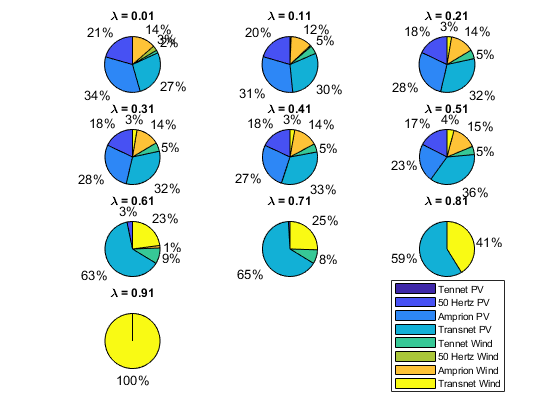

Labels = ["Tennet PV", "50 Hertz PV", "Amprion PV", "Transnet PV", "Tennet Wind", "50 Hertz Wind", "Amprion Wind", "Transnet Wind"];
for i=1:length(xVectors)
 subplot(4,3,i)
 p = pie(xVectors(:,i));
 th = findobj(p,'Type','Text');
 isSmall = startsWith({th.String}, '<');
 isZero = startsWith({th.String}, '0');
 set(th(isZero), 'String', '');
 set(th(isSmall),'String', '');
 title("\lambda = " + lambdas(i), 'Position',[0 1.5]);
 end
hl = legend(Labels, 'Location','eastoutside', 'Orientation','vertical');
newPosition = [0.75 0.15 0.1 0.1];
newUnits = 'normalized';
set(hl,'Position', newPosition,'Units', newUnits)

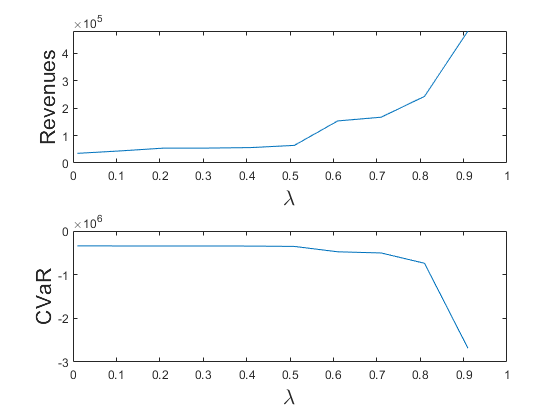

clf;
subplot(2,1,1)
plot(lambdas,Revenues)
xlabel('\lambda', 'Fontsize',16)
ylabel('Revenues', 'Fontsize', 16)
subplot(2,1,2)
plot(lambdas,CVaRs)
xlabel('\lambda', 'Fontsize',16)
ylabel('CVaR', 'Fontsize', 16)

Higher levels of CVaR equal less risks, as in our case we use this measure as a proxy for risk itself.

We can  see how the expected rewards and the portfolio weights change when varying the parameter $\lambda :$ 

- The smaller it is,  the more the decision maker will give importance to containing risk. This results in a well-diversified portfolio of assets, because CVaR largely outweights the expected revenue in the objective function.

- When tha value of $\lambda \;$ approaches 1, the decision is solely focused on maximizing expected returns (i*.e. *almost not taking risk into account), in fact, the portfolio is not diversified at all, and only focused on the "asset" with the maximum expected return.

#### d)

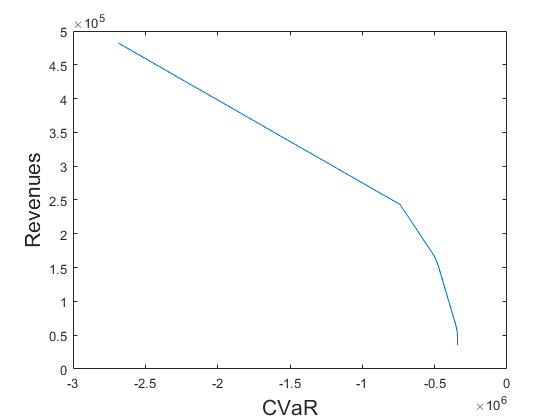

clf;
plot(CVaRs,Revenues)
xlabel('CVaR', 'FontSize',16)
ylabel('Revenues', 'FontSize',16)

There is a noticeable trade-off between expected rewards and risk, which in this case is modeled by CVaR. $\lambda \;$can be considered as a parameter that measures the risk-aversion of the decision maker. In order to have higher expected rewards, it is necessary to be willing to take on a higher level of risk, on the other hand, taking on less risks implies lower expected rewards.

## Exercise 5.3)

#### *a)*


$$max_{x_w,x_c,x_b,e_h^s,e_l^s,y_w^s,y_c^s} \ \ \lambda[S^{-1} \sum_{s=1}^S(R_s)]+(1-\lambda)[t-\alpha^{-1}(\sum_{s=1}^S(z_sp_s))]\\

s.t. \\
x_w + x_c + x_b \leq 500 \\ 
p_w^s \cdot x_w + y_w^s - w_w^s = 200  \ \ \forall \ s\in S \\
p_c^s \cdot x_c + y_c^s - w_c^s = 240  \ \ \forall \ s\in S \\
p_b^s \cdot x_b - e_H^s - e_L^s = 0  \ \ \forall \ s\in S \\
e_H^s \leq 6000 \ \ \forall \ s\in S \\
w_w^s,w_c^s, e_H^s, e_L^s, y_w^s, y_w^s \geq 0 \ \ \forall \ s\in S \\
z_s \geq 0 \ \ \forall \ s\in S \\
z_s \geq t - R_s \ \ \forall \ s\in S \\
x_w , x_c , x_b \geq 0\\$$


#### b)

clear;
load data_farmer_cvar.mat;
alpha = 0.05;
lambda = 0.5;
S = length(yields);
R = sdpvar(S,1);
x = sdpvar(3,1);
w_W = sdpvar(S,1); w_C = sdpvar(S,1);
e_H = sdpvar(S,1); e_L = sdpvar(S,1);
y_W = sdpvar(S,1); y_C = sdpvar(S,1);
t = sdpvar(1);
z = sdpvar(S,1);
p = zeros(S,1);
p(:) = 1/S;

Costs = [150 230 260]; %W;C;B
Cons = [];
Cons = [Cons, sum(x) <= 500];
for s=1:S
    Cons = [Cons, yields(s,1)* x(1) + y_W(s) - w_W(s) == 200];
    Cons = [Cons, yields(s,2)* x(2) + y_C(s) - w_C(s) == 240];
    Cons = [Cons, yields(s,3)* x(3) - e_H(s) - e_L(s) == 0];
    Cons = [Cons, e_H(s)<=6000];
    Cons = [Cons, R(s) == ((170 * w_W(s) + 150 * w_C(s) + 36 * e_H(s) + 10 * e_L(s) - 238 * y_W(s) - 210*y_C(s)) - Costs*x)];
    Cons = [Cons, [w_W(s); w_C(s); e_H(s); e_L(s); y_W(s); y_C(s)] >=0 ];
    Cons = [Cons, z(s)>= 0];
    Cons = [Cons, z(s) >= t - R(s)];
end
Cons = [Cons, x>=0];

CVaR = t - (sum(z.*p,1)/alpha);
Obj = lambda * mean(R) + (1-lambda)*CVaR;

Ops = sdpsettings ('solver','gurobi', 'verbose', 0);
Result = optimize(Cons, -Obj, Ops);

Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 13004 rows, 8004 columns and 30006 nonzeros
Model fingerprint: 0xaf4447ba
Coefficient statistics:
  Matrix range     [9e-01, 3e+02]
  Objective range  [5e-04, 5e-01]
  Bounds range     [0e+00, 0e+00]
  RHS range        [2e+02, 6e+03]

Concurrent LP optimizer: dual simplex and barrier
Showing barrier log only...

Presolve removed 9003 rows and 1000 columns
Presolve time: 0.08s
Presolved: 4001 rows, 7004 columns, 20003 nonzeros

Ordering time: 0.00s

Barrier statistics:
 Dense cols : 4
 Free vars  : 1
 AA' NZ     : 1.000e+04
 Factor NZ  : 2.601e+04 (roughly 5 MBytes of memory)
 Factor Ops : 1.740e+05 (less than 1 second per iteration)
 Threads    : 1

                  Objective                Residual
Iter       Primal          Dual         Primal    Dual     Compl     

Objective = value(Obj)

Objective = 2.3624e+03

MeanR = value(mean(R))

MeanR = 3.7541e+04

Wheat = value(x(1))

Wheat = 232.5931

Corn = value(x(2))

Corn = 109.7318

Sugar_Beet = value(x(3))

Sugar_Beet = 157.6750

CVaR = value(CVaR)

CVaR = -3.2817e+04

#### c)

clear;
load data_farmer_cvar.mat;
alpha = 0.05;
Revenues = [];
lambdas=[];
CVaRs = [];
j = 0;
xVectors = zeros(3,10);
for lambda=0.01:0.1:0.99
j = j+1;
%lambda = 0.5;
S = length(yields);
R = sdpvar(S,1);
x = sdpvar(3,1);
w_W = sdpvar(S,1); w_C = sdpvar(S,1);
e_H = sdpvar(S,1); e_L = sdpvar(S,1);
y_W = sdpvar(S,1); y_C = sdpvar(S,1);
t = sdpvar;
z = sdpvar(S,1);
p = zeros(S,1);
p(:) = 1/S;

Costs = [150 230 260]; %W;C;B
Cons = [];
Cons = [Cons, sum(x) <= 500];
for s=1:S
    Cons = [Cons, yields(s,1)* x(1) + y_W(s) - w_W(s) == 200];
    Cons = [Cons, yields(s,2)* x(2) + y_C(s) - w_C(s) == 240];
    Cons = [Cons, yields(s,3)* x(3) - e_H(s) - e_L(s) == 0];
    Cons = [Cons, e_H(s)<=6000];
    Cons = [Cons, R(s) == ((170 * w_W(s) + 150 * w_C(s) + 36 * e_H(s) + 10 * e_L(s) - 238 * y_W(s) - 210*y_C(s)) - Costs*x)];
    Cons = [Cons, [w_W(s); w_C(s); e_H(s); e_L(s); y_W(s); y_C(s)] >=0 ];
    Cons = [Cons, z(s)>= 0];
    Cons = [Cons, z(s) >= t - R(s)];
end
Cons = [Cons, x>=0];

CVaR = t - (sum(z.*p,1)/alpha);
Obj = lambda * mean(R) + (1-lambda)*CVaR;

Ops = sdpsettings ('solver','gurobi', 'verbose', 0);
Result = optimize(Cons, -Obj, Ops);

Revenues = [Revenues, mean(value(R))];
lambdas = [lambdas, value(lambda)];
CVaRs = [CVaRs, value(CVaR)];
xVectors(:,j) = value(x)';
end

Academic license - for non-commercial use only - expires 2021-06-11
Gurobi Optimizer version 9.1.1 build v9.1.1rc0 (win64)
Thread count: 2 physical cores, 4 logical processors, using up to 4 threads
Optimize a model with 13004 rows, 8004 columns and 30006 nonzeros
Model fingerprint: 0x6e9392c5
Coefficient statistics:
  Matrix range     [9e-01, 3e+02]
  Objective range  [1e-05, 1e+00]
  Bounds range     [0e+00, 0e+00]
  RHS range        [2e+02, 6e+03]

Concurrent LP optimizer: dual simplex and barrier
Showing barrier log only...

Presolve removed 9003 rows and 1000 columns
Presolve time: 0.08s
Presolved: 4001 rows, 7004 columns, 20003 nonzeros

Ordering time: 0.00s

Barrier statistics:
 Dense cols : 4
 Free vars  : 1
 AA' NZ     : 1.000e+04
 Factor NZ  : 2.601e+04 (roughly 5 MBytes of memory)
 Factor Ops : 1.740e+05 (less than 1 second per iteration)
 Threads    : 1

                  Objective                Residual
Iter       Primal          Dual         Primal    Dual     Compl     

#### d)

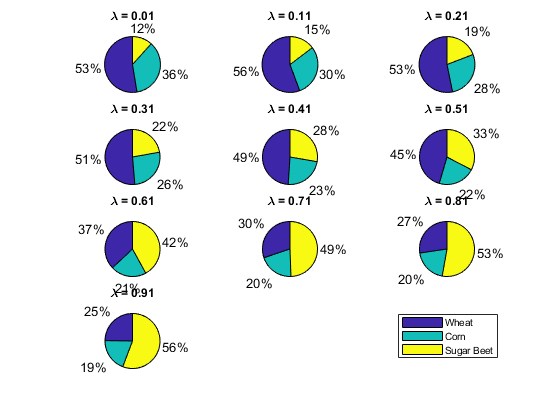

Labels = ["Wheat", "Corn", "Sugar Beet"];
for i=1:length(xVectors)
 subplot(4,3,i)
 p = pie(xVectors(:,i));
 th = findobj(p,'Type','Text');
 isSmall = startsWith({th.String}, '<');
 isZero = startsWith({th.String}, '0');
 set(th(isZero), 'String', '');
 set(th(isSmall),'String', '');
 title("\lambda = " + lambdas(i), 'Position',[0 1.5]);
 end
hl = legend(Labels, 'Location','eastoutside', 'Orientation','vertical');
newPosition = [0.75 0.15 0.1 0.1];
newUnits = 'normalized';
set(hl,'Position', newPosition,'Units', newUnits)

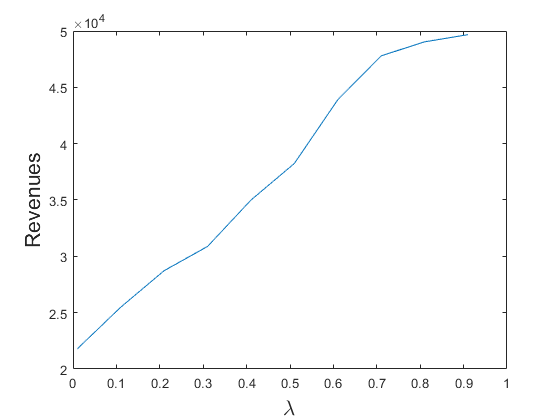

clf;
subplot(2,1,1)
plot(lambdas,Revenues)
xlabel('\lambda', 'Fontsize',16)
ylabel('Revenues', 'Fontsize', 16)
subplot(2,1,2)
plot(lambdas,CVaRs)
xlabel('\lambda', 'Fontsize',16)
ylabel('CVaR', 'Fontsize', 16)

As in the previous exercise, higher values of $\lambda$ reduce decision maker's risk aversion, leading to higher revenues. For higher values of $\lambda$, the farmer tends to plant and sell less wheat and corn, and give more space to sugar beet, that potentally has a higher margin of profit. In this case, on average, the farmer happens to buy more corn and wheat because of the riskier choice made at the beginning.

#### d)

clf;
plot(value(CVaRs),Revenues);
xlabel('CVaR', 'FontSize',16)
ylabel('Revenues', 'FontSize',16);

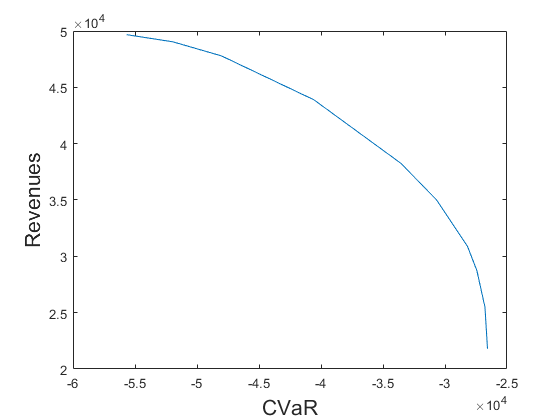

clf;

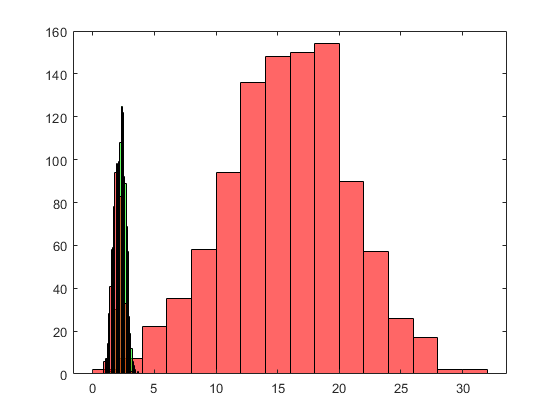

Labels = ["Wheat", "Corn", "Sugar Beet"];
histogram(yields(:,3),'FaceColor','r')
hold on
histogram(yields(:,2),'FaceColor','g')
histogram(yields(:,1),'FaceColor','r')
hold off

Higher expected rewards require lower CVaR values (taking on higher risk), as well as higher value of the CVaR require to give up a margin of profit.

The distribution of sugar beet's yields on the scenarios show that sugar beet can be considered the most risky crop, as well as the most potentially profitable one (mean 15.8707, std. 5.0015). The yields of the other two crops are substantially less profitable volatile (wheat: mean 2.0077 and std. 0.3989, corn: mean 2.4039 and std. 0.3502).